## Adaptation du réseau neuronal 

% chargement du cnn googlenet
net = googlenet

net =   DAGNetwork with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'output'}


% récupération des layers 
lay = net.Layers

lay =   144×1 Layer array with layers:

     1   'data'                           Image Input                   224×224×3 images with 'zerocenter' normalization
     2   'conv1-7x7_s2'                   Convolution                   64 7×7×3 convolutions with stride [2  2] and padding [3  3  3  3]
     3   'conv1-relu_7x7'                 ReLU                          ReLU
     4   'pool1-3x3_s2'                   Max Pooling                   3×3 max pooling with stride [2  2] and padding [0  1  0  1]
     5   'pool1-norm1'                    Cross Channel Normalization   cross channel normalization with 5 channels per element
     6   'conv2-3x3_reduce'               Convolution                   64 1×1×64 convolutions with stride [1  1] and padding [0  0  0  0]
     7   'conv2-relu_3x3_reduce'          ReLU                          ReLU
     8   'conv2-3x3'                      Convolution                  

% voir les détails de la input layer
inLayer = lay(1)

inLayer =   ImageInputLayer with properties:

                      Name: 'data'
                 InputSize: [224 224 3]

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [224×224×3 single]


% connaître le format d'image en entrée
inSize = inLayer.InputSize

inSize =    224   224     3


% récupération des layers (structure du réseau)
lgraph = layerGraph(net);
% création d'une couche neuronale pour 38 classes
newFc = fullyConnectedLayer(38,"Name","new_fc");
% on remplace la couche existante par la nouvelle
lgraph = replaceLayer(lgraph,"loss3-classifier",newFc)

lgraph =   LayerGraph with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'output'}


% création d'une couche output vierge
newOut = classificationLayer("Name","new_out");
% on remplace la couche existante par la nouvelle
lgraph = replaceLayer(lgraph,"output",newOut)

lgraph =   LayerGraph with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'new_out'}


## Image datastores

% création du datastore à partir du répertoire "imgAll"
% les labels seront extraits des noms des répertoires
% le datastore prend "imgAll" et tous les sous-répertoires
imds = imageDatastore("imgAll", "IncludeSubfolders",true, "LabelSource","foldernames")

imds =   ImageDatastore with properties:

                       Files: {
                              ' ...\00075aa8-d81a-4184-8541-b692b78d398a___FREC_Scab 3335.JPG';
                              ' ...\01a66316-0e98-4d3b-a56f-d78752cd043f___FREC_Scab 3003.JPG';
                              ' ...\01a66316-0e98-4d3b-a56f-d78752cd043f___FREC_Scab 3003_270deg.JPG'
                               ... and 70292 more
                              }
                     Folders: {
                              'D:\cecile\Prof\Matlab\SI-IA-PlantDiseases\imgAll'
                              }
                      Labels: [Apple___Apple_scab; Apple___Apple_scab; Apple___Apple_scab ... and 70292 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
               

imds.Labels

ans = 70295×1 categorical array
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 


% Répartition aléatoire des images, 
% 70% pour le training
% 30% pour le test
[trainAllImgs, testAllImgs] = splitEachLabel(imds, 0.7, "randomized")

trainAllImgs =   ImageDatastore with properties:

                       Files: {
                              ' ...\00075aa8-d81a-4184-8541-b692b78d398a___FREC_Scab 3335.JPG';
                              ' ...\01a66316-0e98-4d3b-a56f-d78752cd043f___FREC_Scab 3003_90deg.JPG';
                              ' ...\01f3deaa-6143-4b6c-9c22-620a46d8be04___FREC_Scab 3112.JPG'
                               ... and 49204 more
                              }
                     Folders: {
                              'D:\cecile\Prof\Matlab\SI-IA-PlantDiseases\imgAll'
                              }
                      Labels: [Apple___Apple_scab; Apple___Apple_scab; Apple___Apple_scab ... and 49204 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
        

testAllImgs =   ImageDatastore with properties:

                       Files: {
                              ' ...\01a66316-0e98-4d3b-a56f-d78752cd043f___FREC_Scab 3003.JPG';
                              ' ...\01a66316-0e98-4d3b-a56f-d78752cd043f___FREC_Scab 3003_270deg.JPG';
                              ' ...a66316-0e98-4d3b-a56f-d78752cd043f___FREC_Scab 3003_new30degFlipLR.JPG'
                               ... and 21085 more
                              }
                     Folders: {
                              'D:\cecile\Prof\Matlab\SI-IA-PlantDiseases\imgAll'
                              }
                      Labels: [Apple___Apple_scab; Apple___Apple_scab; Apple___Apple_scab ... and 21085 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "p

% augmentedDatastore permet d'ajouter une fonction de pré-traitement
% ici on adapte la taille de l'image au cnn
trainds = augmentedImageDatastore([224 224],trainAllImgs);
testds = augmentedImageDatastore([224 224],testAllImgs);

## Entraînement du réseau

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:11 |        6.25% |       5.7812 |          0.0100 |
|       1 |          50 |       00:05:56 |       59.38% |       1.4397 |          0.0100 |
|       1 |         100 |       00:11:41 |       76.56% |       0.7109 |          0.0100 |
|       1 |         150 |       00:17:24 |       78.12% |       0.8188 |          0.0100 |
|       1 |         200 |       00:23:07 |       93.75% |       0.3224 |          0.0100 |
|       1 |         250 |       00:28:50 |       92.19% |       0.3133 |          0.0100 |
|       1 |         300 |  

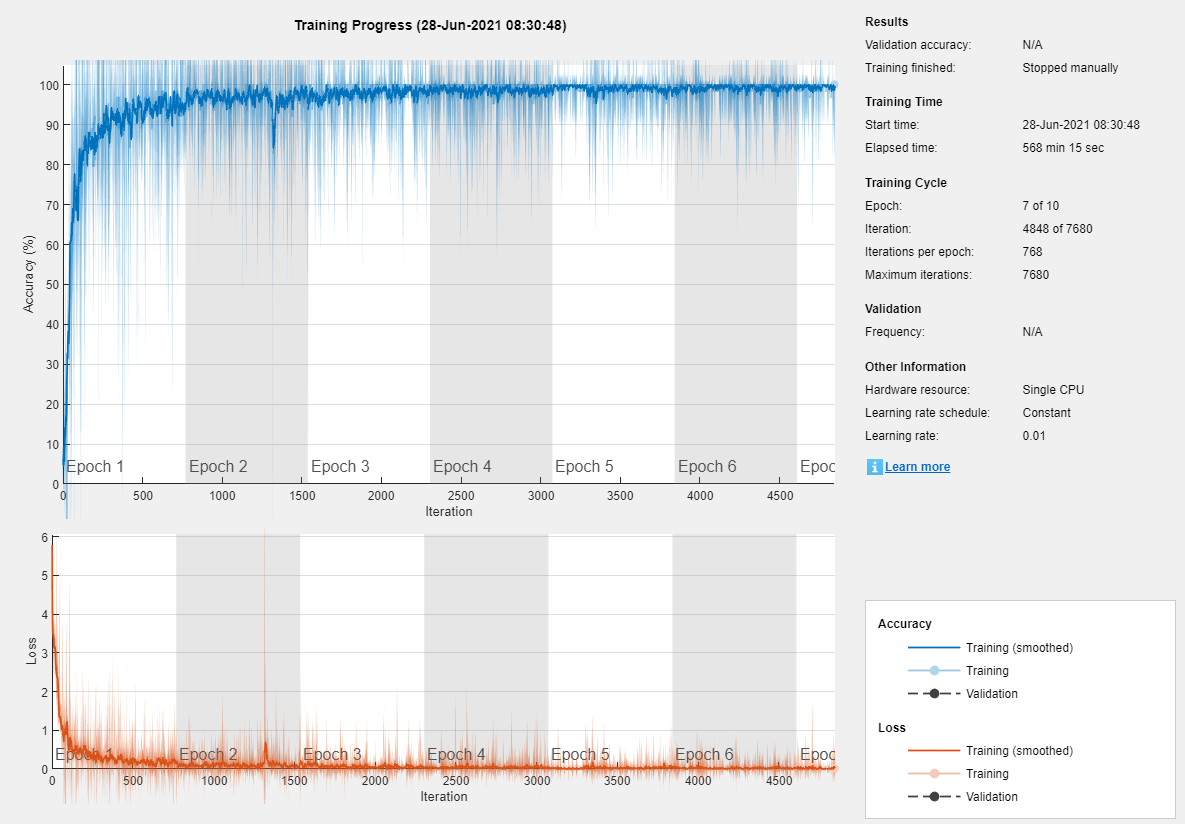

plantDiseasesNet =   DAGNetwork with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'new_out'}


options = trainingOptions("sgdm",...
    'InitialLearnRate', 0.01, ...
    'LearnRateDropFactor',0.2, ...
    'LearnRateDropPeriod',5, ...
    'MaxEpochs',10, ...
    'MiniBatchSize',64, ...
    'Plots','training-progress',...
    'Shuffle','every-epoch');
    
% entraînement du cnn. Temps de calcul important !!
plantDiseasesNet = trainNetwork(trainds,lgraph,options)

% ne pas oublier de sauvegarder !!!!
save ("plantDiseasesNet")

## Evaluation du réseau sur les données de test

% calcule la classe prédite sur les images de test
predictions = classify(plantDiseasesNet,testds)

predictions = 21088×1 categorical array
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 
     Apple___Apple_scab 


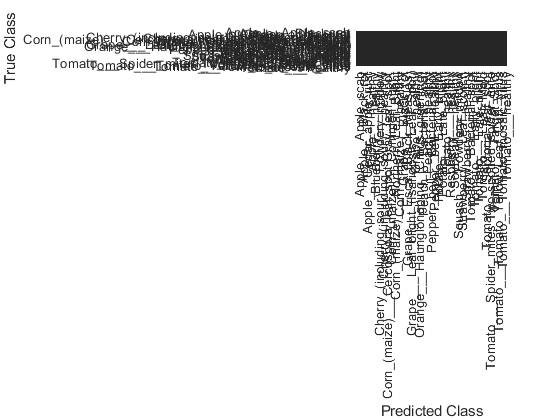

% Trace la matrice de confusion
confusionchart(testAllImgs.Labels, predictions)

## Temps d'exécution sur une image

img = imread("img/Corn__Cercospora_leaf_spot Gray_leaf_spot/0a01cc10-3892-4311-9c48-0ac6ab3c7c43___RS_GLSp 9352.JPG" );
img = imresize(img, [224,224]);
tic
label = classify (plantDiseasesNet,img)

label = categorical
     Corn_(maize)___Cercospora_leaf_spot Gray_leaf_spot 


toc

Elapsed time is 1.378213 seconds.
